# Q2. Image Classification Using Spectrogram *(25 points)*

## 0. Importing Data

The data contains a flute sound signal and its sampling rate.

load("fluteSound.mat")

## 1. Data Preprocessing Using Spectrogram (5)

###     1.1. Plot the data (1)

      Create a plot of the `flute` signal

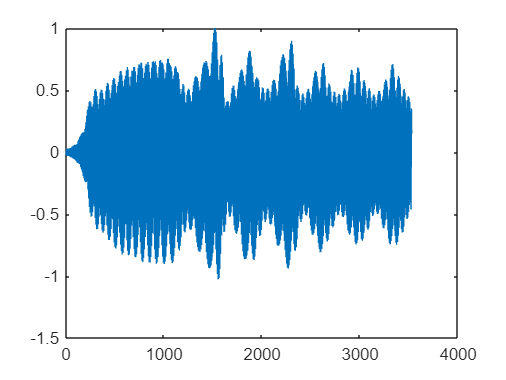

plot(flute)

###     1.2. Spectrogram (2)

      Create a spectrogram of the `flute` signal. The sample rate is stored in a variable named `fs`.

p = pspectrum(flute,fs,"spectrogram");

###     1.3. Prepare image for image classification input (2)

      Remove the plot annotations(axis labels, colorbar, and title).

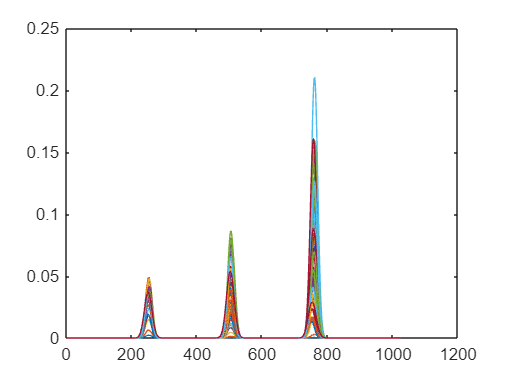

figure
plot(p)

#### 'Q2_Spectrograms' folder contains the spectrogram images of three muscial instruments.

## 2. Preparing Data (4)

###     2.1. Create an image datastore (2)

      Create an image datastore which references the folder of the dataset.

imageDS = imageDatastore("Q2_Spectrograms","IncludeSubfolders",true,"LabelSource","foldernames");

###     2.2. Split dataset (2)

      Split the datastore into train(0.8) and test(0.2) data. **DO NOT include validation dataset.**

[trainData,testData] = splitEachLabel(imageDS,0.8);

## 3. Modifying Network Using 'Deep Network Designer' (5)

Modify appropriate layers of **GoogLeNet** so that the network works for your dataset and then, export the network into your workspace. 

- **Note that the input image size should be ****227 x 227****.**

- **Be sure to ****name your network 'net_1' and include it into the zip file****, when you submit your answer.**

## 4. Training Network (4)

###     4.1. Create training options (2)

      The training options you **SHOULD KEEP** are as follows. The rest of training options are tunerable.

- Max Epochs: 10

- Display training progress and accuracy for the training data

      NOTE: If you train the network using CPU, install 'Parallel Computing Toolbox' to use 'parallel-cpu' option.

opts = trainingOptions("sgdm","Plots","training-progress","Metrics","accuracy",...
    "MaxEpochs",10,"InitialLearnRate",0.001,"LearnRateSchedule","piecewise","LearnRateDropPeriod",8);

###     4.2. Train Network (2)

%load net_google.mat
net_1 = trainnet(trainData,net_google,"crossentropy",opts)

## 5. Evaluating network (7)

Evaluate the network by classifying the test data, calculating the classification accuracy and displaying a confusion chart.

###     5.1. Predict the class of the test data (2)

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:16        0.001          1.5243              50.781
           30       10       00:07:56       0.0001         0.14533              95.312
훈련이 중지됨: 최대 Epoch 완료됨


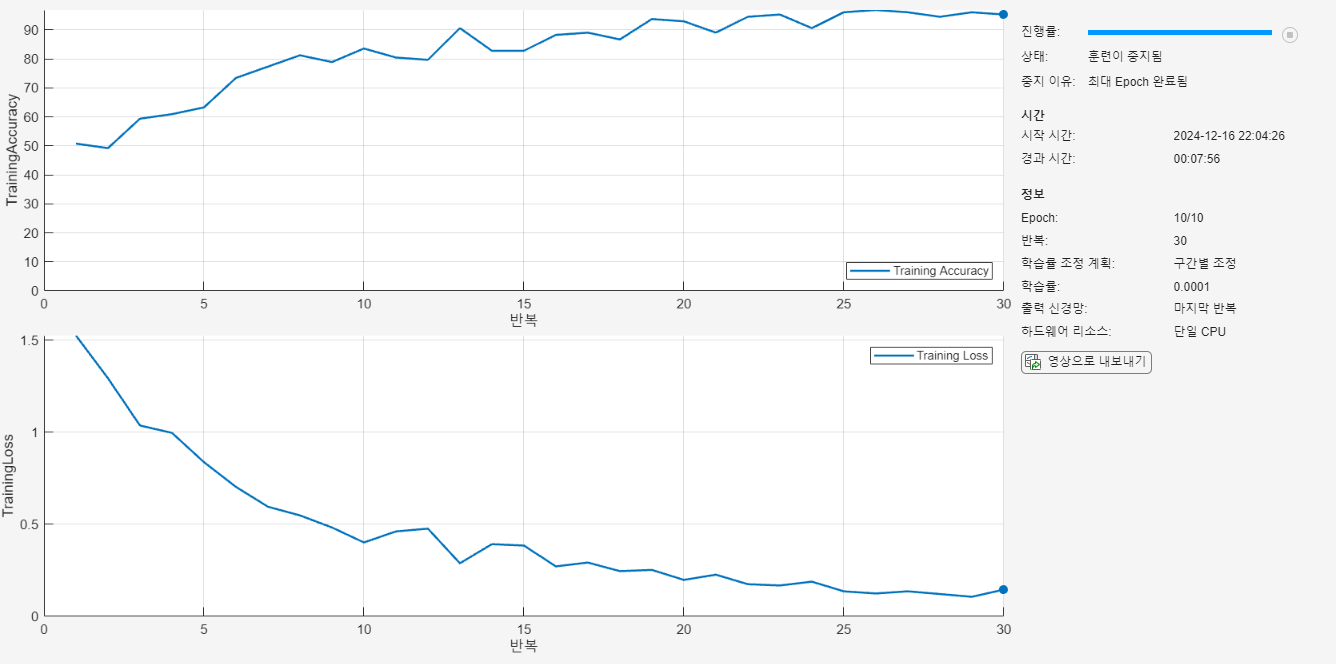

net_1 =   dlnetwork - 속성 있음:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]
     Learnables: [116×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  요약 보기(summary 참조).


classes = categories(imageDS.Labels)

scores = minibatchpredict(net_1,testData);
[testPred,score] = scores2label(scores,classes);

###     5.2. Calculate the prediction accuracy (4)

      Calculate the prediction accuracy on the test data.

- Accuracy >= 0.95             : 4 points

- 0.90 <= Accuracy < 0.95  : 2 points

- Accuracy < 0.90               : 1 points

testGT = testData.Labels

classes = 3×1 cell 배열
    {'Cello'}
    {'Flute'}
    {'Piano'}


testAcc = sum(testPred==testGT) / numel(testPred)

###     5.3. Display a confusion chart (1)

testGT = 113×1 categorical 배열
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 
     Cello 


testAcc = 0.8584

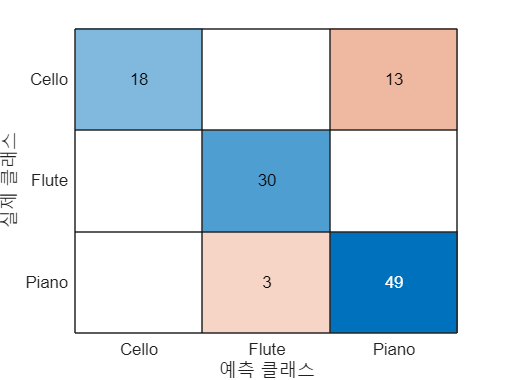

confusionchart(testGT,testPred)